## Problem Statement

For the processes and controllers below, analyze the stability of cascade control system

Primary Process: $G_{p 1} = \frac{1.0 \exp (-4 s)}{(10 s+1)} $

Secondary Process: $G_{p 2} = \frac{5 \exp (- s)}{2 s+1}$

Primary Controller: $G_{c 1} = 2.5 \left( 1 + \frac{1.0}{5 s} \right)$

Secondary Controller: $G_{c 2} = 0.1 $

## Solution

We analyze the primary and secondary loops separately. First we close the secondary loop and assess its behavior. Then we analyze the primary loop.

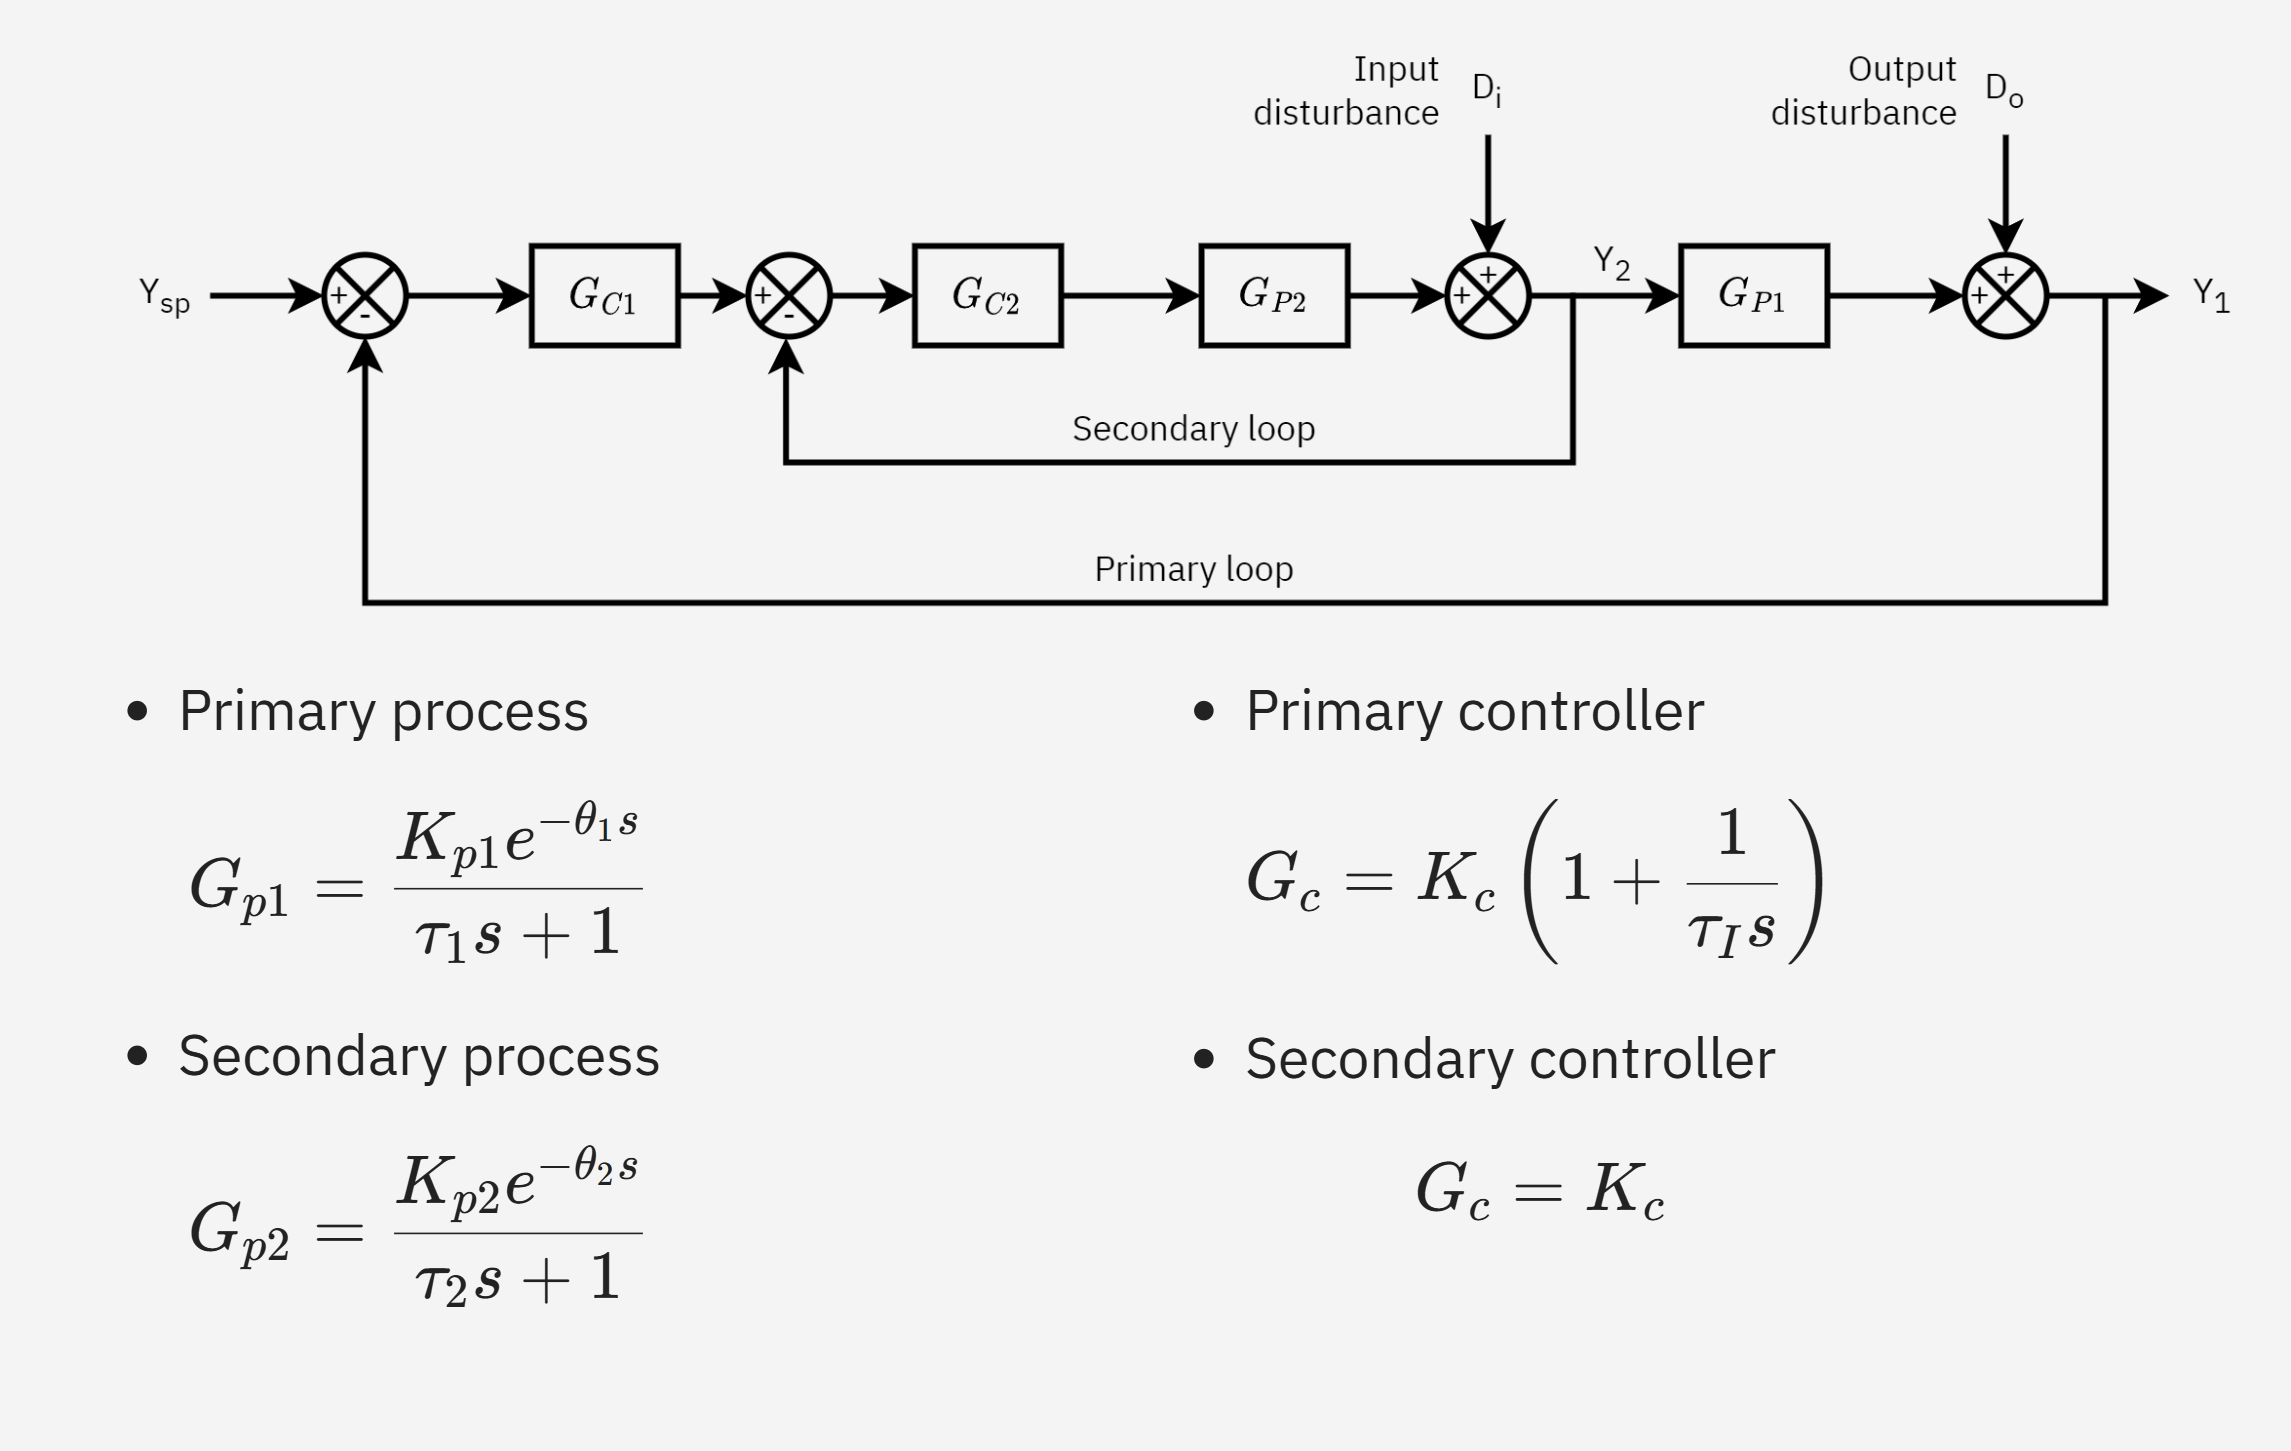

% G_p1
kp1 = 1.0;
theta1 = 4;
tau1 = 10;

num = [kp1]; 
den = [tau1 1]; 

gp1 = tf(num, den, 'InputDelay', theta1)

gp1 =
 
                 1
  exp(-4*s) * --------
              10 s + 1
 
Continuous-time transfer function.
Model Properties



% G_p2
kp2 = 5.0;
theta2 = 1;
tau2 = 2;
gp2 = tf([kp2], [tau2 1], 'InputDelay', theta2)

gp2 =
 
                 5
  exp(-1*s) * -------
              2 s + 1
 
Continuous-time transfer function.
Model Properties



% G_c1
s = tf('s');

kc1 = 2.5;
tauI1 = 5.0;
gc1 = 2.5 * (1 + 1/(tauI1*s))

gc1 =
 
  12.5 s + 2.5
  ------------
      5 s
 
Continuous-time transfer function.
Model Properties



% G_c2

kc2 = 0.1;
gc2 = tf([kc2])

gc2 =
 
  0.1
 
Static gain.
Model Properties



% Calculate KL2 = K_c2*K_p2
KL2 = dcgain(gc2) * dcgain(gp2)

KL2 = 0.5000

## Secondary loop analysis

% Inner loop characteristic equation
T_inner = 1 + gc2*gp2 

T_inner =
 
  A = 
         x1
   x1  -0.5
 
  B = 
        u1
   x1  0.5
 
  C = 
        x1
   y1  0.5
 
  D = 
       u1
   y1   1
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 1 
 
Continuous-time state-space model.



% Returns a state space. We need to approximate delay time

% Simplified approximation e^(-θs) = 1-θs
delay = 1 - theta2* s;
gp2_approx = (kp2*delay)/(tau2*s + 1)

gp2_approx =
 
  -5 s + 5
  --------
  2 s + 1
 
Continuous-time transfer function.
Model Properties



Gcl2_approx = feedback(gc2*gp2_approx,1)

Gcl2_approx =
 
  -0.5 s + 0.5
  ------------
  1.5 s + 1.5
 
Continuous-time transfer function.
Model Properties


den = Gcl2_approx.Denominator{1};  % Extract denominator coefficients
poles = roots(den)

poles = -1

isstable(Gcl2_approx)

ans = logical
   1


% First order Pade approximation e^(-θs) = [1-(θ/2)s]/[1+(θ/2)s]
gp2_pade = pade(gp2,1)

gp2_pade =
 
     -5 s + 10
  ---------------
  2 s^2 + 5 s + 2
 
Continuous-time transfer function.
Model Properties



Gcl2_pade = feedback(gc2*gp2_pade,1)

Gcl2_pade =
 
     -0.5 s + 1
  -----------------
  2 s^2 + 4.5 s + 3
 
Continuous-time transfer function.
Model Properties


den = Gcl2_pade.Denominator{1}  % Extract denominator coefficients

den =     2.0000    4.5000    3.0000



poles = roots(den)

poles =   -1.1250 + 0.4841i
  -1.1250 - 0.4841i


isstable(Gcl2_pade)

ans = logical
   1


## Primary loop analysis

% Augmented primary process

gp1_pade = pade(gp1,1)

gp1_pade =
 
       -s + 0.5
  ------------------
  10 s^2 + 6 s + 0.5
 
Continuous-time transfer function.
Model Properties


Gpa = Gcl2_pade*gp1_pade

Gpa =
 
           0.5 s^2 - 1.25 s + 0.5
  ----------------------------------------
  20 s^4 + 57 s^3 + 58 s^2 + 20.25 s + 1.5
 
Continuous-time transfer function.
Model Properties


Gcl1_pade = feedback(gc1*Gpa,1)

Gcl1_pade =
 
            6.25 s^3 - 14.38 s^2 + 3.125 s + 1.25
  ----------------------------------------------------------
  100 s^5 + 285 s^4 + 296.2 s^3 + 86.88 s^2 + 10.62 s + 1.25
 
Continuous-time transfer function.
Model Properties


den = Gcl1_pade.Denominator{1}  % Extract denominator coefficients

den =   100.0000  285.0000  296.2500   86.8750   10.6250    1.2500



poles = roots(den)

poles =   -1.2360 + 0.6742i
  -1.2360 - 0.6742i
  -0.2955 + 0.0000i
  -0.0413 + 0.1401i
  -0.0413 - 0.1401i


isstable(Gcl1_pade)

ans = logical
   1
